# 检测结果

## 点检测

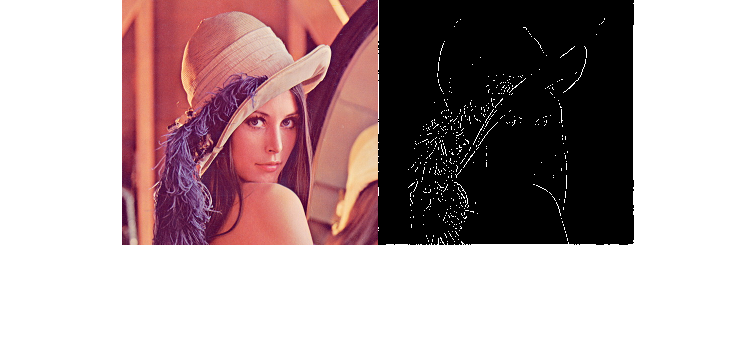

close all
clear
clc

im = imread('test_images/lena.png');
% figure, imshow(im);

pt = point_detection(im);
pt = cat(3, pt, pt, pt);
pt = uint8(pt * 255);
im_pair = cat(2, im, pt);
figure, imshow(im_pair);

## 线检测

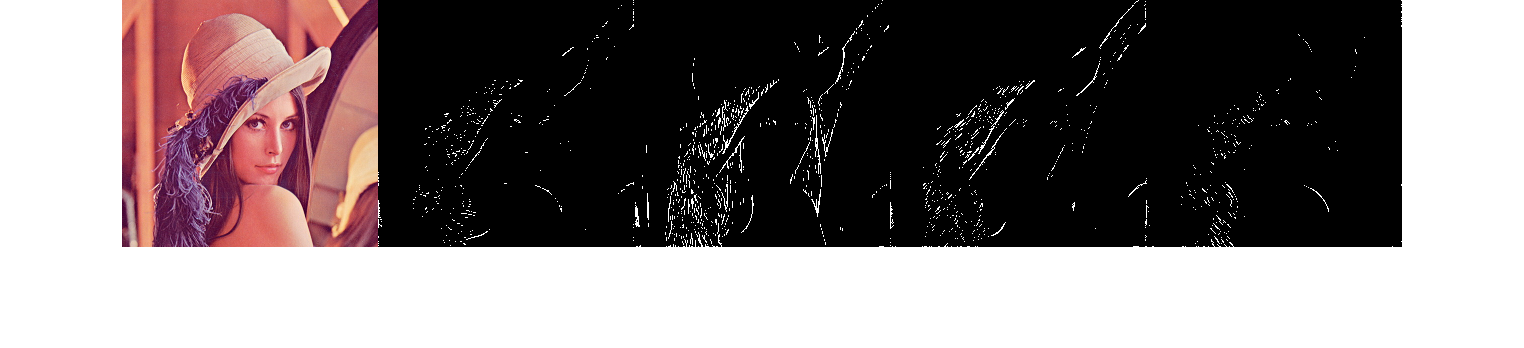

close all
clear
clc

im = imread('test_images/lena.png');
% figure, imshow(im);

% 水平方向
filter = [-1, -1, -1; ...
           4,  4,  4; ...
          -1, -1, -1];
lt_h = line_detection(im, filter);
lt_h = cat(3, lt_h, lt_h, lt_h);
lt_h = uint8(lt_h * 255);
% figure, imshow(lt_h);

% 垂直方向
filter = [-1,  4, -1; ...
          -1,  4, -1; ...
          -1,  4, -1];
lt_v = line_detection(im, filter);
lt_v = cat(3, lt_v, lt_v, lt_v);
lt_v = uint8(lt_v * 255);
% figure, imshow(lt_v);

% 45°方向
filter = [-1, -1,  4; ...
          -1,  4, -1; ...
           4, -1, -1];
lt_45 = line_detection(im, filter);
lt_45 = cat(3, lt_45, lt_45, lt_45);
lt_45 = uint8(lt_45 * 255);
% figure, imshow(lt_45);

% 135°方向
filter = [ 4, -1, -1; ...
          -1,  4, -1; ...
          -1, -1,  4];
lt_135 = line_detection(im, filter);
lt_135 = cat(3, lt_135, lt_135, lt_135);
lt_135 = uint8(lt_135 * 255);
% figure, imshow(lt_135);
% show
im_pair = cat(2, im, lt_h, lt_v, lt_45, lt_135);
figure, imshow(im_pair)

## 边缘检测

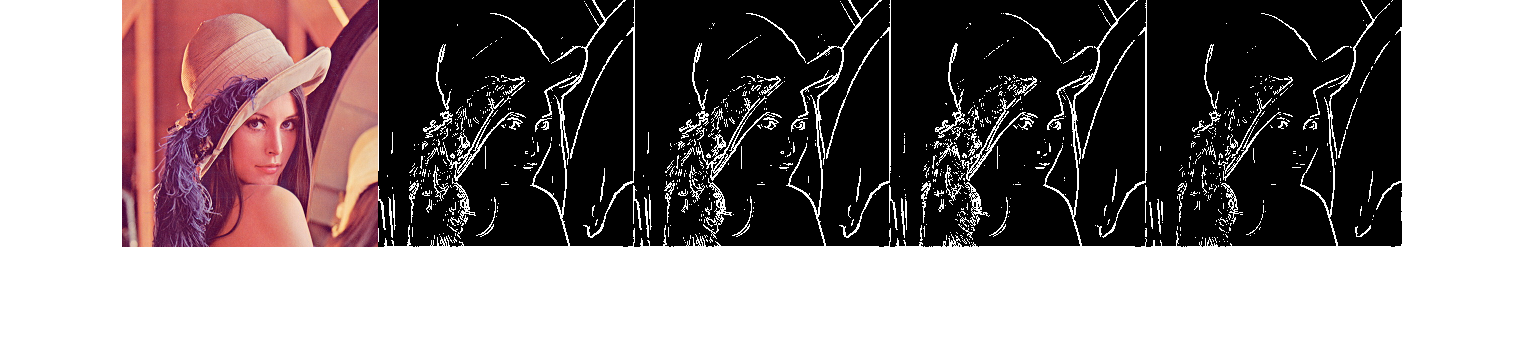

close all
clear
clc

im = imread('test_images/lena.png');
% figure, imshow(im);

% 
type = 'prewitt';
et_pre = edge_detection(im, type);
et_pre = cat(3, et_pre, et_pre, et_pre);
et_pre = uint8(et_pre * 255);
% figure, imshow(et_pre);

% 
type = 'sobel';
et_sob = edge_detection(im, type);
et_sob = cat(3, et_sob, et_sob, et_sob);
et_sob = uint8(et_sob * 255);
% figure, imshow(et_sob);

% 
type = 'robinson';
et_rob = edge_detection(im, type);
et_rob = cat(3, et_rob, et_rob, et_rob);
et_rob = uint8(et_rob * 255);
% figure, imshow(et_rob);

% 
type = 'kirsh';
et_kir = edge_detection(im, type);
et_kir = cat(3, et_kir, et_kir, et_kir);
et_kir = uint8(et_kir * 255);
% figure, imshow(et_kir);

% show
im_pair = cat(2, im, et_pre, et_sob, et_rob, et_kir);
figure, imshow(im_pair)